# Mixing tank model and behaviour

This livescript is a brief manual in support of the app ***mixingtank_and_behaviour.mlapp***.   This is a simple interface to understand the modelling and behaviour of simple mixing tank models, subject to changes in the core parameters such as tank volume, flow rate, inlet concentration, reaction rate and disturbances to the inlet flow.    

A logical next file is ***tanklevel***.***mlapp*** which looks at how to control the tank concentration using a PI compensator.

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files  uncomment and run either line of the code below (using run section):**

% doc Control101 Toolbox  % this line works even if toolbox not installed
%
% help control101  % this line only works if the toolbox is installed

File written by J.A.Rossiter, University of Sheffield                         

## Table of contents

- Engineering context

- Open-loop behaviour: time constant and gain analysis

- Impact of a reaction

- Impact of changes to other parameters

- Impact of disturbances

- Interface and user interaction of the app file

## 1. Engineering context

We consider a tank with an inlet and outlet pipes and a constant flow rate. 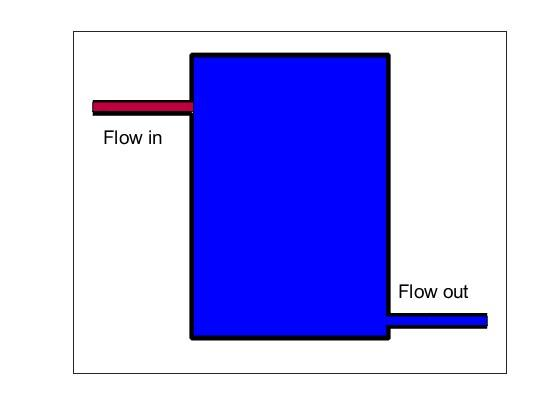

The inlet concentration is not the same as the outlet concentration and thus, assuming good mixing, the tank will gradually change concentration (colour). A typical model is given as:

$V\frac{\textrm{dC}}{\textrm{dt}}+\textrm{FC}=FC_{\textrm{in}} \;$ where *V* is the tank volume, *F* is the flow rate, *C* is the concentration in the tank and $C_{\textrm{in}}$ is the concentration of the inlet flow.

This model can be rearranged into time constant form to reveal time constant *T=V/F* and gain *K=1*:


$$V\frac{\textrm{dC}}{\textrm{dt}}+\textrm{FC}=FC_{\textrm{in}} \;\;\Rightarrow \frac{V}{F}\frac{\textrm{dC}}{\textrm{dt}}+C=C_{\textrm{in}} \;\;\;\Rightarrow \;T\frac{\textrm{dC}}{\textrm{dt}}+C=C_{\textrm{in}}$$


In practice there may also be a reaction taking place within the tank that affects concentration. A suitable updated model, assuming the usage of the core chemical is proportional to the concentration is given as:


$$V\frac{\textrm{dC}}{\textrm{dt}}+\textrm{FC}=FC_{\textrm{in}} -\textrm{rVC}\;\Rightarrow \frac{V}{\left(F+\textrm{rV}\right)}\frac{\textrm{dC}}{\textrm{dt}}+C={\frac{F}{\left(F+\textrm{rV}\right)}C}_{\textrm{in}} \;\;\;\Rightarrow \;T\frac{\textrm{dC}}{\textrm{dt}}+C={\textrm{KC}}_{\textrm{in}} ,\;\;\;\;\;\;\;\;T=\frac{V}{\left(F+\textrm{rV}\right)},K=\frac{F}{\left(F+\textrm{rV}\right)}$$


 It is notable that the reaction makes both the time constant smaller and the steady-state gain smaller.

## 2. Open-loop behaviour: time constant and gain analysis

One can determine the overall response using standard 1st order responses, so, assuming the inlet concentration is constant: 


$$C\left(t\right)=KC_{\textrm{in}} \left(1-e^{-\frac{t}{T}} \right)+C\left(0\right)e^{-\frac{t}{T}}$$


% Model parameters
V=2; F=0.1; r=0.0; C0=0.1; Cin=0.4;
T = V/(F + V*r)

T = 20

K = F/(F + V*r)

K = 1

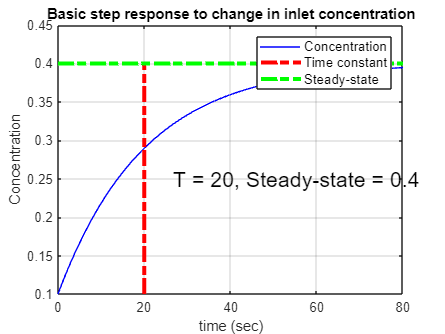

runtime = round(4*T/10)*10;

% Define the step responses
time=linspace(0,runtime,101);
expterm = exp(-time/T);
ct = K*Cin*(1-expterm) + C0*expterm;
steadyvalue = K*Cin;
steadylineplot = ones(1,length(time))*steadyvalue;

% Plot response
plot(time,ct,'b');
hold('on') ;
plot([T,T],[C0,steadyvalue],'r-.','linewidth',3)
plot([0,runtime],[1,1]*steadyvalue,'g-.','linewidth',3)
kkk=legend('Concentration','Time constant','Steady-state');
set(kkk,'fontsize',10);
pos = (C0+steadyvalue)/2;
text(runtime/3,pos,['T = ',num2str(T),', Steady-state = ',num2str(steadyvalue)],'fontsize', 16);
xlabel('time (sec)');
ylabel('Concentration')
grid('on');
hold('off');
title('Basic step response to change in inlet concentration')

## 3. Impact of a reaction

As noted above, a reaction changes the time constant and gain. Thus can be illustrated simply here.

disp('**********************************************')

**********************************************


disp('Section 3 below - impact of a reaction ')

Section 3 below 


% model parameters with a reaction
r=0.02;
T2 = V/(F + V*r)

T2 = 14.2857

K2 = F/(F + V*r)

K2 = 0.7143

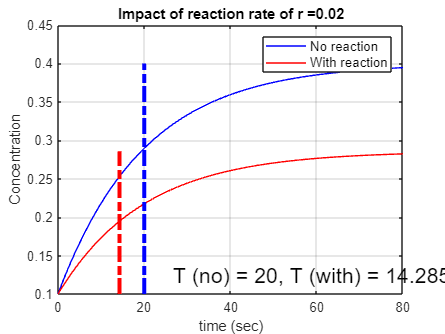

% Define the step responses with a reaction
time=linspace(0,runtime,101);
expterm2 = exp(-time/T2);
ct2 = K2*Cin*(1-expterm) + C0*expterm;
steadyvalue2 = K2*Cin;
steadylineplot2 = ones(1,length(time))*steadyvalue;

% Overlay response with and without reactioin
plot(time,ct,'b',time,ct2,'r');
hold('on') ;
plot([T,T],[C0,steadyvalue],'b-.','linewidth',3)
plot([T2,T2],[C0,steadyvalue2],'r-.','linewidth',3)
kkk=legend('No reaction','With reaction');
set(kkk,'fontsize',10);
text(runtime/3,pos/2,['T (no) = ',num2str(T),', T (with) = ',num2str(T2)],'fontsize', 16);
xlabel('time (sec)');
ylabel('Concentration')
grid('on');
hold('off');
title(['Impact of reaction rate of r =', num2str(r)])

## 4. Impact of changes to other parameters

Users might also like to investigate the impact of changes in flow rate and tank volume, initial condition, inlet concentration and so forth. The app is the easiest vehicle for such investigations, although code similar to the above would also work (e.g. define appropriate *K2, T2* for the different model).

## 5. Impact of disturbances

A simple disturbance could be a temporary change in inlet concentration, perhaps due to leakage or contamination. For simplicity the app discussed below will introduce such a disturbance for a fixed time scale, from about 2 to 3  time constants. The user can select the magnitude of the inlet concentration disturbance; **set magnitude to zero for no disturbance**.

## 6. Interface and user interaction of the app file

The user can change 6 parameters and thus investigage easily the impact of changes. The parameters can only take a finite number of discrete values, as on the sliders, to avoid excessive decimal places.

- The top figure shows the tank and inlet/outlet pipes. The dimensions of these change to reflect volume and flow rate. The colour changes to reflect concentration (red for low concentration and blue for high concentration).

- The bottom right figure overlays all recent choices so the comparison is easy to view.

- The bottom left figure shows the time constant and gain analysis for the current choices.

- The top figure illustrates and allows visualisation of the concentration (colour changes) and volume (tank size) and flow rate (inlet and outlet dimensions).

The app will overlay all recent responses so the comparison is clear - simulations run for about 5 time constants, so are parameter choice dependent. The legend keeps track of key parameter choices not obvious from the graph. To refresh and begin again, use the refresh button.

You can disable the animation to see quicker responses using the 'animation on/off' button.